clc; clear; close all;
close all force;

%% =====================================================================
%  USER SETTINGS
%% =====================================================================
baseFolder         = 'C:\Users\USER\Desktop\2. Evaluation form\3. SNTV-2\2. 16-June';
yesterdayESSFolder = 'C:\Users\USER\Desktop\2. Evaluation form\3. SNTV-2\1. 15-June\ESS'; % <<< CHANGE

dtTick = minutes(30);

Pylim_MW    = [-80 80];
Pticks_MW   = [-80 -40 0 40 80];
Qylim_Mvar  = [-25 25];
Qticks_Mvar = [-25 -12.5 0 12.5 25];

red    = [0.8 0 0];
colVab = [0 0.447 0.741];
colVbc = [0.466 0.674 0.188];
colVca = [0.494 0.184 0.556];

%% =====================================================================
%  AUTO FIND INPUT FILES
%% =====================================================================
file_SOCFV = dir(fullfile(baseFolder, '*Voltage*SOC*POC*Point*.xlsx'));
file_PQ    = dir(fullfile(baseFolder, '*P*Q*POC*Point*.xlsx'));
file_PVS   = dir(fullfile(baseFolder, '*PV*Smoothing*.xlsx'));

if isempty(file_SOCFV)
    error('Cannot find SOC/F/V file. Expect: *Voltage*SOC*POC*Point*.xlsx');
end
if isempty(file_PQ)
    error('Cannot find P/Q file. Expect: *P*Q*POC*Point*.xlsx');
end

socfvPath = fullfile(baseFolder, file_SOCFV(1).name);
pqPath    = fullfile(baseFolder, file_PQ(1).name);

fprintf('SOC/F/V file: %s\n', file_SOCFV(1).name);

SOC/F/V file: 1-F-Voltage_SOC_POC_Point_2026-06-16_20260617000807.xlsx


fprintf('P/Q file    : %s\n', file_PQ(1).name);

P/Q file    : 1-P_Q-POC-Point_2026-06-16_20260617000817.xlsx



hasPVS = ~isempty(file_PVS);
if hasPVS
    pvsPath = fullfile(baseFolder, file_PVS(1).name);
    fprintf('PV smoothing file: %s\n', file_PVS(1).name);
else
    warning('PV smoothing file not found. Expect: *PV*Smoothing*.xlsx');
end

PV smoothing file: PV_Smoothing_SvayRieng_2026-06-16_20260617000827.xlsx



%% =====================================================================
%  READ & CLEAN TABLES
%% =====================================================================
T1 = readtable(socfvPath, 'PreserveVariableNames', true);
T2 = readtable(pqPath,    'PreserveVariableNames', true);

T1 = T1(~ismember(string(T1{:,1}), ["Average","Max","Min"]), :);
T2 = T2(~ismember(string(T2{:,1}), ["Average","Max","Min"]), :);

T1.Time = datetime(string(T1{:,1}), 'InputFormat', 'yyyy-MM-dd HH:mm:ss');
T2.Time = datetime(string(T2{:,1}), 'InputFormat', 'yyyy-MM-dd HH:mm:ss');

T1 = standardizeMissing(T1, "--");
T2 = standardizeMissing(T2, "--");

vars1 = T1.Properties.VariableNames;
for i = 2:width(T1)
    col = T1.(vars1{i});
    if iscell(col) || isstring(col) || ischar(col), col = str2double(string(col)); end
    col = fillmissing(col, 'previous', 'EndValues', 'nearest');
    col = fillmissing(col, 'next');
    T1.(vars1{i}) = col;
end

vars2 = T2.Properties.VariableNames;
for i = 2:width(T2)
    col = T2.(vars2{i});
    if iscell(col) || isstring(col) || ischar(col), col = str2double(string(col)); end
    col = fillmissing(col, 'previous', 'EndValues', 'nearest');
    col = fillmissing(col, 'next');
    T2.(vars2{i}) = col;
end

T1 = T1(~isnat(T1.Time), :);
T2 = T2(~isnat(T2.Time), :);

%% =====================================================================
%  EXTRACT COLUMNS
%% =====================================================================
SOC    = T1{:,2};
F      = T1{:,3};
Vab    = T1{:,4};
Vbc    = T1{:,5};
Vca    = T1{:,6};
P_kW   = T2{:,2};
Q_kVAr = T2{:,3};

%% =====================================================================
%  TIMETABLES & ALIGN
%% =====================================================================
TT1 = timetable(T1.Time, SOC, F, Vab, Vbc, Vca, ...
    'VariableNames', {'SOC','F','Vab','Vbc','Vca'});
TT2 = timetable(T2.Time, P_kW, Q_kVAr, ...
    'VariableNames', {'P_kW','Q_kVAr'});
TT  = synchronize(TT1, TT2, 'intersection');

if height(TT) == 0
    warning('Intersection empty. Using union + fillmissing.');
    TT = synchronize(TT1, TT2, 'union');
    TT = fillmissing(TT, 'previous', 'EndValues', 'nearest');
    TT = fillmissing(TT, 'next');
end

%% =====================================================================
%  SMARTLOGGER -> TT5
%% =====================================================================
smartFolder = fullfile(baseFolder, 'SmartLogger');
smartFiles  = dir(fullfile(smartFolder, 'SmartLogger_*.xlsx'));

if isempty(smartFiles)
    warning('No SmartLogger_*.xlsx found in: %s', smartFolder);
    TT5 = timetable('Size',[0 2],'VariableTypes',{'double','double'}, ...
                    'VariableNames',{'TotalP_MW','TotalQ_MVar'}, ...
                    'RowTimes',datetime.empty(0,1));
else
    TTsumP = []; TTsumQ = [];
    for k = 1:numel(smartFiles)
        fpath = fullfile(smartFolder, smartFiles(k).name);
        Ts    = readtable(fpath,'Range','A4','PreserveVariableNames',true);
        vnames  = lower(string(Ts.Properties.VariableNames));
        idxTime = find(contains(vnames,"start") & contains(vnames,"time"),1);
        if isempty(idxTime), idxTime = find(contains(vnames,"time"),1); end
        if isempty(idxTime), idxTime = 1; end
        idxP = 5; idxQ = 26;
        t_s    = datetime(string(Ts{:,idxTime}),'InputFormat','yyyy-MM-dd HH:mm:ss');
        p_kW   = Ts{:,idxP};   if ~isnumeric(p_kW),   p_kW   = str2double(string(p_kW));   end
        q_kVAr = Ts{:,idxQ};   if ~isnumeric(q_kVAr), q_kVAr = str2double(string(q_kVAr)); end
        valid  = ~isnat(t_s);
        t_s = t_s(valid); p_kW = p_kW(valid); q_kVAr = q_kVAr(valid);
        TTkP = timetable(t_s, p_kW,   'VariableNames',{sprintf('P%d_kW',k)});
        TTkQ = timetable(t_s, q_kVAr, 'VariableNames',{sprintf('Q%d_kVAr',k)});
        if isempty(TTsumP), TTsumP = TTkP; else, TTsumP = synchronize(TTsumP,TTkP,'union'); end
        if isempty(TTsumQ), TTsumQ = TTkQ; else, TTsumQ = synchronize(TTsumQ,TTkQ,'union'); end
    end
    TTsumP = fillmissing(TTsumP,'constant',0);
    TTsumQ = fillmissing(TTsumQ,'constant',0);
    TTsumP.TotalP_MW   = sum(TTsumP{:,1:end},2) / 1000;
    TTsumQ.TotalQ_MVar = sum(TTsumQ{:,1:end},2) / 1000;
    TT5 = synchronize(TTsumP(:,{'TotalP_MW'}), TTsumQ(:,{'TotalQ_MVar'}),'union');
    TT5 = fillmissing(TT5,'constant',0);
    disp('✅ SmartLogger SUM done -> TT5.TotalP_MW and TT5.TotalQ_MVar');
end

✅ SmartLogger SUM done -> TT5.TotalP_MW and TT5.TotalQ_MVar



%% =====================================================================
%  PV SMOOTHING
%% =====================================================================
if hasPVS
    optsPVS = detectImportOptions(pvsPath,'Sheet',1,'TextType','string');
    optsPVS.DataRange = 'A5';
    TPVS = readtable(pvsPath, optsPVS);
    t_pvs = datetime(string(TPVS{:,1}),'InputFormat','yyyy-MM-dd HH:mm:ss');
    Ppcc  = str2double(string(TPVS{:,2})) / 1000;
    Ppv   = str2double(string(TPVS{:,4})) / 1000;
    Pess  = str2double(string(TPVS{:,5})) / 1000;
    SOCp  = str2double(string(TPVS{:,6}));
    Ppcc  = fillmissing(fillmissing(Ppcc,'previous','EndValues','nearest'),'next');
    Ppv   = fillmissing(fillmissing(Ppv, 'previous','EndValues','nearest'),'next');
    Pess  = fillmissing(fillmissing(Pess,'previous','EndValues','nearest'),'next');
    SOCp  = fillmissing(fillmissing(SOCp,'previous','EndValues','nearest'),'next');
    good  = ~isnat(t_pvs);
    t_pvs = t_pvs(good); Ppcc = Ppcc(good); Ppv = Ppv(good);
    Pess  = Pess(good);  SOCp = SOCp(good);
end


%% =====================================================================
%  FINAL SERIES
%% =====================================================================
t      = TT.Time;
P_MW   = TT.P_kW   / 1000;
Q_MVar = TT.Q_kVAr / 1000;
SOC    = TT.SOC;
F      = TT.F;
Vab    = TT.Vab;
Vbc    = TT.Vbc;
Vca    = TT.Vca;

%% =====================================================================
%  RAW FILE STRUCTS (ESS / PCS / SmartLogger)
%% =====================================================================
rawESS = struct(); rawPCS = struct(); rawSmart = struct();
mkField = @(fn) matlab.lang.makeValidName(erase(fn, {'.xlsx','.xls'}));

essFolder = fullfile(baseFolder, 'ESS');
if isfolder(essFolder)
    essFiles = [dir(fullfile(essFolder,'*.xlsx')); dir(fullfile(essFolder,'*.xls'))];
    for k = 1:numel(essFiles)
        fpath = fullfile(essFolder, essFiles(k).name);
        key   = mkField(essFiles(k).name);
        try,    rawESS.(key) = readtable(fpath,'PreserveVariableNames',true);
        catch,  rawESS.(key) = readtable(fpath,'PreserveVariableNames',true,'ReadVariableNames',true); end
    end
else
    warning('ESS folder not found: %s', essFolder);
end

pcsFolder = fullfile(baseFolder, 'PCS');
if isfolder(pcsFolder)
    pcsFiles = [dir(fullfile(pcsFolder,'*.xlsx')); dir(fullfile(pcsFolder,'*.xls'))];
    for k = 1:numel(pcsFiles)
        fpath = fullfile(pcsFolder, pcsFiles(k).name);
        key   = mkField(pcsFiles(k).name);
        try,    rawPCS.(key) = readtable(fpath,'PreserveVariableNames',true);
        catch,  rawPCS.(key) = readtable(fpath,'PreserveVariableNames',true,'ReadVariableNames',true); end
    end
else
    warning('PCS folder not found: %s', pcsFolder);
end

if isfolder(smartFolder)
    smartFilesAll = [dir(fullfile(smartFolder,'*.xlsx')); dir(fullfile(smartFolder,'*.xls'))];
    for k = 1:numel(smartFilesAll)
        fpath = fullfile(smartFolder, smartFilesAll(k).name);
        key   = mkField(smartFilesAll(k).name);
        try,    rawSmart.(key) = readtable(fpath,'PreserveVariableNames',true);
        catch,  rawSmart.(key) = readtable(fpath,'PreserveVariableNames',true,'ReadVariableNames',true); end
    end
end

%% =====================================================================
%  ESS EQUIVALENT CYCLE — TODAY  (D_today = avg of last cycle per device)
%% =====================================================================
TTcycle       = timetable('Size',[0 1],'VariableTypes',{'double'}, ...
                          'VariableNames',{'AvgCycles'}, ...
                          'RowTimes',datetime.empty(0,1));
TTallCyc      = [];
dailyCycleAvg = NaN;
totalCycleAvg = NaN;

perDeviceTotal = [];

if isfolder(essFolder)
    essFilesAll = [dir(fullfile(essFolder,'*.xlsx')); dir(fullfile(essFolder,'*.xls'))];
    nESS = numel(essFilesAll);

    for k = 1:nESS
        fpath = fullfile(essFolder, essFilesAll(k).name);
        try
            Tess   = readtable(fpath,'PreserveVariableNames',true,'VariableNamingRule','preserve');
            vnames = string(Tess.Properties.VariableNames);
            vlow   = lower(vnames);

            idxT = find(contains(vlow,"start") & contains(vlow,"time"),1);
            if isempty(idxT), idxT = find(contains(vlow,"time"),1); end
            if isempty(idxT)
                for ci = 1:min(5,width(Tess))
                    try
                        datetime(string(Tess{1,ci}),'InputFormat','yyyy-MM-dd HH:mm:ss');
                        idxT = ci; break;
                    catch, end
                end
            end
            if isempty(idxT), idxT = 4; end

            idxC = find(contains(vlow,"equivalent") & contains(vlow,"cycle"),1);
            if isempty(idxC), idxC = find(contains(vlow,"cycle"),1); end
            if isempty(idxC), idxC = 6; end

            fprintf('  [Cycle] %s | time col=%d | cycle col=%d (%s)\n', ...
                essFilesAll(k).name, idxT, idxC, vnames(idxC));

            rawT  = string(Tess{:,idxT});
            t_ess = NaT(size(rawT));
            for ri = 1:numel(rawT)
                try, t_ess(ri) = datetime(rawT(ri),'InputFormat','yyyy-MM-dd HH:mm:ss'); catch, end
            end

            cyc = Tess{:,idxC};
            if ~isnumeric(cyc), cyc = str2double(string(cyc)); end

            isSummary = ismember(string(Tess{:,1}),["Average","Max","Min"]);
            good = ~isnat(t_ess) & ~isnan(cyc) & ~isSummary;
            t_ess = t_ess(good); cyc = cyc(good);

            if isempty(t_ess)
                warning('[Cycle] %s: no valid rows.', essFilesAll(k).name); continue
            end

            perDeviceTotal(end+1) = cyc(end);

            TTk = timetable(t_ess, cyc, 'VariableNames',{sprintf('Cyc%d',k)});
            if isempty(TTallCyc), TTallCyc = TTk;
            else,                 TTallCyc = synchronize(TTallCyc,TTk,'union'); end

        catch ME
            warning('[Cycle] Failed: %s | %s', essFilesAll(k).name, ME.message);
        end
    end

    if ~isempty(TTallCyc)
        TTallCyc           = fillmissing(TTallCyc,'previous','EndValues','nearest');
        TTallCyc           = fillmissing(TTallCyc,'next');
        TTallCyc.AvgCycles = mean(TTallCyc{:,1:end},2,'omitnan');
        TTcycle            = TTallCyc(:,{'AvgCycles'});

        totalCycleAvg = mean(perDeviceTotal, 'omitnan');
        fprintf('✅ ESS Today | Total Plant Avg (D_today) = %.4f\n', totalCycleAvg);
    end
end

  [Cycle] ESS_10254C719811_13553_20260616000000_20260616235959.xlsx | time col=4 | cycle col=46 (Equivalent number of cycles)
  [Cycle] ESS_10254C719830_14123_20260616000000_20260616235959.xlsx | time col=4 | cycle col=46 (Equivalent number of cycles)
  [Cycle] ESS_10254C719854_13574_20260616000000_20260616235959.xlsx | time col=4 | cycle col=46 (Equivalent number of cycles)
  [Cycle] ESS_10254C719856_14102_20260616000000_20260616235959.xlsx | time col=4 | cycle col=46 (Equivalent number of cycles)
  [Cycle] ESS_102555358614_13595_20260616000000_20260616235959.xlsx | time col=4 | cycle col=46 (Equivalent number of cycles)
  [Cycle] ESS_102555358629_14081_20260616000000_20260616235959.xlsx | time col=4 | cycle col=46 (Equivalent number of cycles)


✅ ESS Today | Total Plant Avg (D_today) = 198.6667



%% =====================================================================
%  ESS EQUIVALENT CYCLE — YESTERDAY  (D_yesterday = avg of last cycle per device)
%% =====================================================================
D_yesterday        = NaN;
perDeviceYesterday = [];

if isfolder(yesterdayESSFolder)
    essFilesYest = [dir(fullfile(yesterdayESSFolder,'*.xlsx')); ...
                    dir(fullfile(yesterdayESSFolder,'*.xls'))];

    for k = 1:numel(essFilesYest)
        fpath = fullfile(yesterdayESSFolder, essFilesYest(k).name);
        try
            Ty     = readtable(fpath,'PreserveVariableNames',true,'VariableNamingRule','preserve');
            vlow   = lower(string(Ty.Properties.VariableNames));

            idxC = find(contains(vlow,"equivalent") & contains(vlow,"cycle"),1);
            if isempty(idxC), idxC = find(contains(vlow,"cycle"),1); end
            if isempty(idxC), idxC = 6; end

            cycY = Ty{:,idxC};
            if ~isnumeric(cycY), cycY = str2double(string(cycY)); end
            cycY = cycY(~isnan(cycY));

            if ~isempty(cycY)
                perDeviceYesterday(end+1) = cycY(end);
            end
        catch ME
            warning('[Yesterday Cycle] Failed: %s | %s', essFilesYest(k).name, ME.message);
        end
    end

    if ~isempty(perDeviceYesterday)
        D_yesterday = mean(perDeviceYesterday, 'omitnan');
        fprintf('✅ ESS Yesterday | Total Plant Avg (D_yesterday) = %.4f\n', D_yesterday);
    end
else
    warning('Yesterday ESS folder not found: %s', yesterdayESSFolder);
end

✅ ESS Yesterday | Total Plant Avg (D_yesterday) = 197.6667



%% =====================================================================
%  DAILY CYCLE  =  D_today - D_yesterday
%% =====================================================================
D_today = totalCycleAvg;

if ~isnan(D_today) && ~isnan(D_yesterday)
    dailyCycleAvg = D_today - D_yesterday;
else
    dailyCycleAvg = NaN;
    warning('Cannot compute Daily Cycle. Check ESS folders.');
end

if ~isnan(dailyCycleAvg) && dailyCycleAvg < 0
    warning('Daily Cycle is NEGATIVE — check ESS data!');
end

fprintf('✅ Daily Cycle = D_today (%.4f) - D_yesterday (%.4f) = %.4f\n', ...
    D_today, D_yesterday, dailyCycleAvg);

✅ Daily Cycle = D_today (198.6667) - D_yesterday (197.6667) = 1.0000


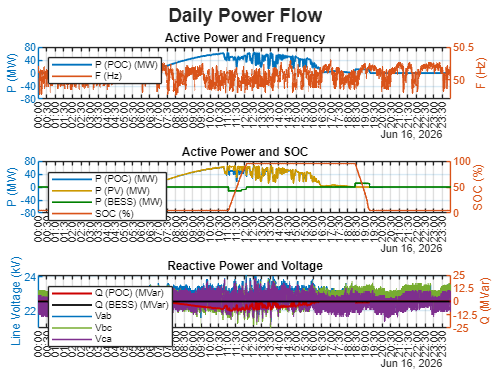


%% =====================================================================
%  FIGURE 1 — THREE-SUBPLOT OVERVIEW
%% =====================================================================
figure('Color','w','Name','Daily Power Flow');
tiledlayout(3,1,'TileSpacing','compact','Padding','compact');

nexttile
yyaxis left;  hP1=stairs(t,P_MW,'LineWidth',1.4); ylabel('P (MW)'); ylim(Pylim_MW); yticks(Pticks_MW);
yyaxis right; hF =plot(t,F,'LineWidth',1.2);       ylabel('F (Hz)');
grid on; title('Active Power and Frequency')
legend([hP1 hF],{'P (POC) (MW)','F (Hz)'},'Location','northwest')
ax=gca; ax.XTick=t(1):dtTick:t(end); xtickformat('HH:mm')

nexttile
yyaxis left
if hasPVS
    hP2 =plot(t_pvs,Ppcc,'-','Color',[0 0.4470 0.7410],'LineWidth',1.3); hold on
    hPV =plot(t_pvs,Ppv, '-','Color',[0.8 0.6 0],      'LineWidth',1.3);
    hESS=plot(t_pvs,Pess,'-','Color',[0 0.5 0],         'LineWidth',1.3);
else
    hP2 =plot(t,P_MW,'-','Color',[0 0.4470 0.7410],'LineWidth',1.3); hold on
    hPV =plot(NaT,NaN,'-','Color',[0.8 0.6 0],'LineWidth',1.3);
    hESS=plot(NaT,NaN,'-','Color',[0 0.5 0],  'LineWidth',1.3);
end
hold off; ylabel('P (MW)'); ylim(Pylim_MW); yticks(Pticks_MW);
yyaxis right
if hasPVS, hSOC=plot(t_pvs,SOCp,'LineWidth',1.2);
else,       hSOC=plot(t,SOC,'LineWidth',1.2); end
ylabel('SOC (%)');
grid on; title('Active Power and SOC')
legend([hP2 hPV hESS hSOC],{'P (POC) (MW)','P (PV) (MW)','P (BESS) (MW)','SOC (%)'},'Location','northwest')
ax=gca; ax.XTick=t(1):dtTick:t(end); xtickformat('HH:mm')

nexttile
yyaxis left;  hVab=plot(t,Vab,'-','LineWidth',1.2,'Color',colVab); hold on
              hVbc=plot(t,Vbc,'-','LineWidth',1.2,'Color',colVbc);
              hVca=plot(t,Vca,'-','LineWidth',1.2,'Color',colVca); hold off
ylabel('Line Voltage (kV)');
yyaxis right
hQ=stairs(t,Q_MVar,'LineWidth',1.5,'Color',red); hold on
if ~isempty(TT5) && height(TT5)>0
    hQB=stairs(TT5.Properties.RowTimes,TT5.TotalQ_MVar,'-','LineWidth',1.4,'Color',[0 0 0]);
else, hQB=stairs(NaT,NaN,'-','LineWidth',1.4,'Color',[0 0 0]); end
hold off; ylabel('Q (MVar)'); ylim(Qylim_Mvar); yticks(Qticks_Mvar);
grid on; title('Reactive Power and Voltage')
legend([hQ hQB hVab hVbc hVca],{'Q (POC) (MVar)','Q (BESS) (MVar)','Vab','Vbc','Vca'},'Location','northwest')
ax=gca; ax.XTick=t(1):dtTick:t(end); xtickformat('HH:mm')
sgtitle('Daily Power Flow','FontSize',14,'FontWeight','bold');

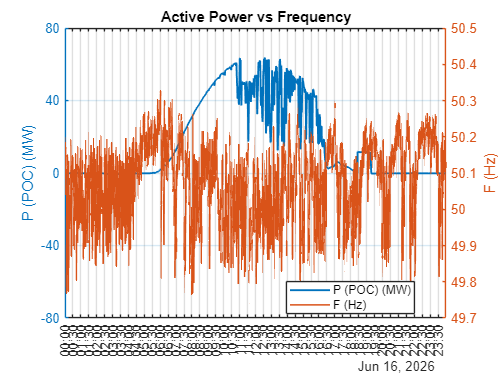


%% SAVE
dayStr    = datestr(t(1),'yyyymmdd');
dateLabel = datestr(t(1),'yyyy-mm-dd');
outFolder = baseFolder;
if ~isfolder(outFolder), mkdir(outFolder); end
saveFig = @(figH,fname) savefig(figH, fullfile(outFolder,fname));

figSub = gcf;
saveFig(figSub, sprintf('1.%s_SNTV12MWH_Powerflow.fig', dayStr));

%% =====================================================================
%  FIGURE 2 — P and F
%% =====================================================================
figPF = figure('Color','w','Name','P and F');
yyaxis left;  hP=stairs(t,P_MW,'LineWidth',1.4); ylabel('P (POC) (MW)'); ylim(Pylim_MW); yticks(Pticks_MW);
yyaxis right; hF=plot(t,F,'LineWidth',1.2);       ylabel('F (Hz)');
grid on; title('Active Power vs Frequency');
legend([hP hF],{'P (POC) (MW)','F (Hz)'},'Location','best');
ax=gca; ax.XTick=t(1):dtTick:t(end); xtickformat('HH:mm');

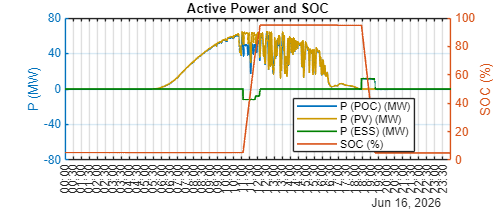

saveFig(figPF, sprintf('2.%s_SNTV12MWH_Frequency_Vs_ActivePower.fig', dayStr));

%% =====================================================================
%  FIGURE 3 — SOC and P
%% =====================================================================
figSOC = figure('Color','w','Name','SOC and P');
set(figSOC,'Units','normalized','Position',[0.1 0.2 0.8 0.6]);
yyaxis left
if hasPVS
    hP  =plot(t_pvs,Ppcc,'-','Color',[0 0.4470 0.7410],'LineWidth',1.3); hold on
    hPV =plot(t_pvs,Ppv, '-','Color',[0.8 0.6 0],      'LineWidth',1.3);
    hESS=plot(t_pvs,Pess,'-','Color',[0 0.5 0],         'LineWidth',1.3);
else
    hP  =plot(t,P_MW,'-','Color',[0 0.4470 0.7410],'LineWidth',1.3); hold on
    hPV =plot(NaT,NaN,'-','Color',[0.8 0.6 0],'LineWidth',1.3);
    hESS=plot(NaT,NaN,'-','Color',[0 0.5 0],  'LineWidth',1.3);
end
hold off; ylabel('P (MW)'); ylim(Pylim_MW); yticks(Pticks_MW);
yyaxis right
if hasPVS, hSOC=plot(t_pvs,SOCp,'LineWidth',1.2);
else,       hSOC=plot(t,SOC,'LineWidth',1.2); end
ylabel('SOC (%)');
grid on; title('Active Power and SOC');
legend([hP hPV hESS hSOC],{'P (POC) (MW)','P (PV) (MW)','P (ESS) (MW)','SOC (%)'},'Location','best');
ax=gca; ax.XTick=t(1):dtTick:t(end); xtickformat('HH:mm');

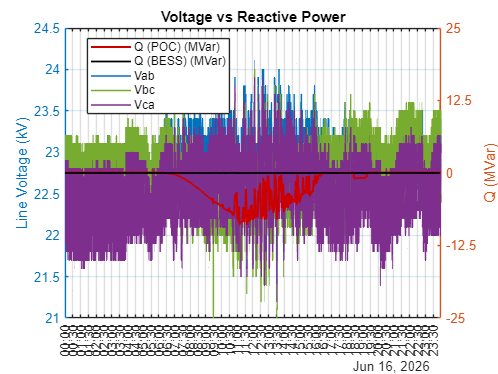

saveFig(figSOC, sprintf('3.%s_SNTV12MWH_SOC_Vs_ActivePower.fig', dayStr));

%% =====================================================================
%  FIGURE 4 — Q and V
%% =====================================================================
figQV = figure('Color','w','Name','Q and V');
yyaxis left
hVab=plot(t,Vab,'-','LineWidth',1.2,'Color',colVab); hold on
hVbc=plot(t,Vbc,'-','LineWidth',1.2,'Color',colVbc);
hVca=plot(t,Vca,'-','LineWidth',1.2,'Color',colVca); hold off
ylabel('Line Voltage (kV)');
yyaxis right
hQ=stairs(t,Q_MVar,'LineWidth',1.5,'Color',red); hold on
if ~isempty(TT5) && height(TT5)>0
    hQB=stairs(TT5.Properties.RowTimes,TT5.TotalQ_MVar,'-','LineWidth',1.4,'Color',[0 0 0]);
else, hQB=stairs(NaT,NaN,'-','LineWidth',1.4,'Color',[0 0 0]); end
hold off; ylabel('Q (MVar)'); ylim(Qylim_Mvar); yticks(Qticks_Mvar);
grid on; title('Voltage vs Reactive Power');
legend([hQ hQB hVab hVbc hVca],{'Q (POC) (MVar)','Q (BESS) (MVar)','Vab','Vbc','Vca'},'Location','best');
ax=gca; ax.XTick=t(1):dtTick:t(end); xtickformat('HH:mm');

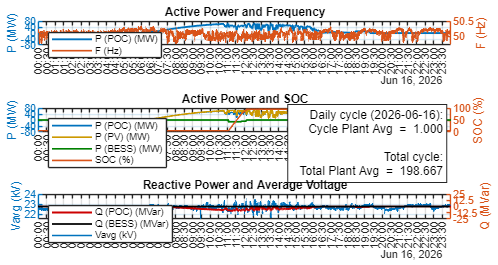

saveFig(figQV, sprintf('4.%s_SNTV12MWH_Voltage_Vs_ReactivePower.fig', dayStr));

%% =====================================================================
%  FIGURE 5 — Daily Power Flow (Vavg)  +  Cycle Label
%% =====================================================================
Vavg = (Vab + Vbc + Vca) / 3;

fig5 = figure('Color','w','Name','Daily Power Flow (Vavg)');
set(fig5,'Units','normalized','Position',[0.05 0.05 0.9 0.85]);
tiledlayout(3,1,'TileSpacing','compact','Padding','compact');

% ---- Subplot 1 : P & F ----
ax1 = nexttile;
yyaxis left;  hP1=stairs(t,P_MW,'LineWidth',1.4); ylabel('P (MW)'); ylim(Pylim_MW); yticks(Pticks_MW);
yyaxis right; hF =plot(t,F,'LineWidth',1.2);       ylabel('F (Hz)');
grid on; title('Active Power and Frequency')
legend([hP1 hF],{'P (POC) (MW)','F (Hz)'},'Location','northwest')
ax1.XTick=t(1):dtTick:t(end); xtickformat('HH:mm')

% ---- Subplot 2 : P / PV / ESS & SOC ----
ax2 = nexttile;
yyaxis left
if hasPVS
    hP2 =plot(t_pvs,Ppcc,'-','Color',[0 0.4470 0.7410],'LineWidth',1.3); hold on
    hPV =plot(t_pvs,Ppv, '-','Color',[0.8 0.6 0],      'LineWidth',1.3);
    hESS=plot(t_pvs,Pess,'-','Color',[0 0.5 0],         'LineWidth',1.3);
else
    hP2 =plot(t,P_MW,'-','Color',[0 0.4470 0.7410],'LineWidth',1.3); hold on
    hPV =plot(NaT,NaN,'-','Color',[0.8 0.6 0],'LineWidth',1.3);
    hESS=plot(NaT,NaN,'-','Color',[0 0.5 0],  'LineWidth',1.3);
end
hold off; ylabel('P (MW)'); ylim(Pylim_MW); yticks(Pticks_MW);
yyaxis right
if hasPVS, hSOC=plot(t_pvs,SOCp,'LineWidth',1.2);
else,       hSOC=plot(t,SOC,'LineWidth',1.2); end
ylabel('SOC (%)');
grid on; title('Active Power and SOC')
legend([hP2 hPV hESS hSOC],{'P (POC) (MW)','P (PV) (MW)','P (BESS) (MW)','SOC (%)'},'Location','northwest')
ax2.XTick=t(1):dtTick:t(end); xtickformat('HH:mm')

% ---- Cycle annotation — bottom-right corner inside ax2 ----
if ~isnan(dailyCycleAvg) && ~isnan(totalCycleAvg)
    labelStr = sprintf('Daily cycle (%s):\n  Cycle Plant Avg  =  %.3f\n\nTotal cycle:\n  Total Plant Avg  =  %.3f', ...
        dateLabel, dailyCycleAvg, totalCycleAvg);

    axes(ax2);
    yyaxis right;
    text(0.98, 0.98, labelStr, ...
        'Units',              'normalized', ...
        'HorizontalAlignment','right', ...
        'VerticalAlignment',  'top', ...
        'FontName',           'Helvetica', ...
        'FontSize',           9, ...
        'BackgroundColor',    'w', ...
        'EdgeColor',          [0.15 0.15 0.15], ...
        'LineWidth',          0.5, ...
        'Interpreter',        'none');
end

% ---- Subplot 3 : Vavg & Q ----
ax3 = nexttile;
yyaxis left
hVavg = plot(t, Vavg, '-', 'LineWidth', 1.2, 'Color', colVab);
ylabel('Vavg (kV)');
yyaxis right
hQ  = stairs(t, Q_MVar, 'LineWidth', 1.5, 'Color', red); hold on
if ~isempty(TT5) && height(TT5) > 0
    hQB = stairs(TT5.Properties.RowTimes, TT5.TotalQ_MVar, '-', 'LineWidth', 1.4, 'Color', [0 0 0]);
else
    hQB = stairs(NaT, NaN, '-', 'LineWidth', 1.4, 'Color', [0 0 0]);
end
hold off; ylabel('Q (MVar)'); ylim(Qylim_Mvar); yticks(Qticks_Mvar);
grid on; title('Reactive Power and Average Voltage')
legend([hQ hQB hVavg], {'Q (POC) (MVar)','Q (BESS) (MVar)','Vavg (kV)'}, 'Location','northwest')
ax3.XTick = t(1):dtTick:t(end); xtickformat('HH:mm')


saveFig(fig5, sprintf('5.%s_SNTV12MWH_Powerflow_Vavg.fig', dayStr));

%% =====================================================================
%  FILE REFERENCES & RAW TABLES
%% =====================================================================
srcFiles             = struct();
srcFiles.baseFolder  = baseFolder;
srcFiles.socfvPath   = socfvPath;
srcFiles.pqPath      = pqPath;
srcFiles.smartFolder = smartFolder;
srcFiles.essFolder   = essFolder;
srcFiles.pcsFolder   = pcsFolder;
if exist('pvsPath','var'), srcFiles.pvsPath = pvsPath; else, srcFiles.pvsPath = ''; end

SOC_RawData = T1;
POC_RawData = T2;
if hasPVS, PVS_RawData = TPVS; else, PVS_RawData = table(); end

%% =====================================================================
%  SAVE .MAT
%% =====================================================================
matName = sprintf('SNTV12MWH_%s_data.mat', dayStr);
matPath = fullfile(baseFolder, matName);

if ~exist('TT5','var') || isempty(TT5)
    TT5 = timetable('Size',[0 2],'VariableTypes',{'double','double'}, ...
                    'VariableNames',{'TotalP_MW','TotalQ_MVar'}, ...
                    'RowTimes',datetime.empty(0,1));
end
if ~exist('TTcycle','var') || isempty(TTcycle)
    TTcycle = timetable('Size',[0 1],'VariableTypes',{'double'}, ...
                        'VariableNames',{'AvgCycles'}, ...
                        'RowTimes',datetime.empty(0,1));
end

save(matPath, ...
    'SOC_RawData','POC_RawData','PVS_RawData', ...
    'rawESS','rawPCS','rawSmart', ...
    'TT','TT5','TTcycle', ...
    'srcFiles', '-v7.3');

fprintf('✅ Saved ALL RAW DATA + TTcycle into:\n   %s\n', matPath);

✅ Saved ALL RAW DATA + TTcycle into:
   C:\Users\USER\Desktop\2. Evaluation form\3. SNTV-2\2. 16-June\SNTV12MWH_20260616_data.mat
